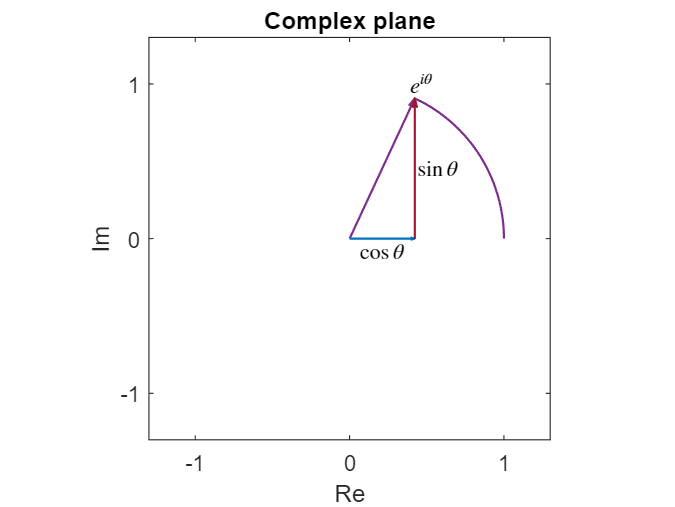

theta = 65;


% This function traces out a circle in the complex plane
% With labels for Euler's formula

f = exp(1i*theta * pi/180);
thetaVec = 0:theta;
fc = exp(1i*thetaVec*pi/180);

colors = lines(7);

figure
quiver(0,0,real(f),imag(f),"off","LineWidth",1,"color",colors(4,:))
hold on
plot(real(fc),imag(fc),"LineWidth",1,"color",colors(4,:))
quiver(0,0,real(f),0,"off","LineWidth",1,"color",colors(1,:))
quiver(real(f),0,0,imag(f),"off","LineWidth",1,"color",colors(7,:))
text(real(f)/2,0,"$\cos \theta$","Interpreter","latex",...
    "VerticalAlignment","top","HorizontalAlignment","center")
text(real(f),imag(f)/2,"$\sin \theta$","Interpreter","latex",...
    "VerticalAlignment","middle","HorizontalAlignment","left")
text(real(f)*1.1,imag(f)*1.1,"$e^{i \theta}$","Interpreter","latex",...
    "VerticalAlignment","middle","HorizontalAlignment","center")
hold off

axis equal
axis(1.3*[-1 1 -1 1])
xlabel("Re")
ylabel("Im")
title("Complex plane")
xticks([-1,0,1])
yticks([-1,0,1])